nvar = 2 ;
lb = [0 -5] ;
ub = [5 0] ;



Optimization terminated: average change in the spread of Pareto solutions less than options.FunctionTolerance.


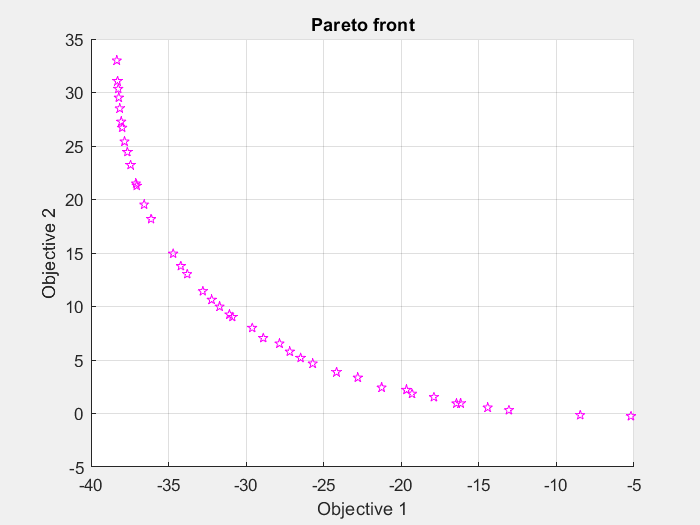

% Set nondefault solver options
options = optimoptions('gamultiobj','PopulationSize',60,'ParetoFraction',0.7,...
    'PlotFcn','gaplotpareto');

% Solve
[solution,objectiveValue] = gamultiobj(@multiObjFcn1,nvar,[],[],[],[],lb,ub,...
    [],options);


% Clear variables
clearvars options

function F = multiObjFcn1 (optimInput)
% Example:
% Minimize F(x,y) where
% F(1) = x^2 + y^2
% F(2) = 2 + 0.5*((x-2)^2 + (y+1)^2)

% Edit the lines below with your calculation
x = optimInput(1);
y = optimInput(2);
F(2) = x^4 + y^4 + x*y -(x*y)^2 ;
F(1) = F(2) - 10*x^2 ;


end

